# Data Generation of Double Pendulum Example

## 1. Load Configuration

Read YAML

config=readyaml("Configuration/DoublePendulum.yaml");

System Parameters from YAML File

global m1 m2 l1 l2 lc1 lc2 J1 J2 g
n=config.DoF;
m1=config.PARAMETER.m1;
m2=config.PARAMETER.m2;
l1=config.PARAMETER.l1;
l2=config.PARAMETER.l2;
g=config.PARAMETER.g;

System Parameter from Computation

lc1=l1/2;
lc2=l2/2;
J1=m1*lc1^2/3;
J2=m2*lc2^2/3;

Verify $M$, $C$, $G$ functions

disp(M_Matrix(0,[0;0;0;0]));

   12.2580    4.5570
    4.5570    2.0580



disp(C_Vector(0,[0;0;0;0]));

     0
     0



disp(G_Vector(0,[0;0;0;0]));

   47.7260
   14.4060



Verify State Space ODE

disp(SS_ODE(0,[0;0;0;0],[0;0]));

         0
         0
   -7.3020
    9.1686



Dataset Settings

num_examples=config.DATASET.NUM_SAMPLES;
time_steps=config.DATASET.TIME_STEPS;
dt=config.DATASET.SAMPLING_TIME;
num_slice=config.DATASET.SOLVER_SLICE;
reltol=config.DATASET.RELTOL;
abstol=config.DATASET.ABSTOL;
option=odeset(RelTol=reltol,AbsTol=abstol);

## 2. Simulation

Initialize Parallel Computing

% parpool(config.DATASET.NUM_WORKERS);

Initialize Dataset and Inital Conditions

Data=zeros((time_steps+1)*num_examples,3*n+1);
for sample=1:num_examples
    % Time History
    Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1),1)=linspace(0,time_steps*dt,time_steps+1);
    % Initial Condition
    Data((sample-1)*(time_steps+1)+1,2:2*n+1)=[0.5*(rand(1,2)-0.5),2*(rand(1,2)-0.5)];
    % Random Input
    Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1)-1,2*n+2:3*n+1)=(rand(time_steps,n)-0.5);
    % NaN Input for End
    Data(sample*(time_steps+1),2*n+2:3*n+1)=NaN;
end

Numerical Simulation

tic
for sample=1:num_examples
    for index=1:time_steps
        % Solution in period
        % dt*[(sample-1)*(time_steps+1)+index,(sample-1)*(time_steps+1)+index+1]
        tspan=dt*linspace((sample-1)*(time_steps+1)+index,(sample-1)*(time_steps+1)+index+1,num_slice+1);
        Input=transpose(Data((sample-1)*(time_steps+1)+index,2*n+2:3*n+1));
        InitalCondition=transpose(Data((sample-1)*(time_steps+1)+index,2:2*n+1));
        [t_temp,State_temp]=ode45(@(t,x)SS_ODE(t,x,Input),tspan,InitalCondition,option);
        Data((sample-1)*(time_steps+1)+index+1,2:2*n+1)=State_temp(end,:);
    end
end
toc

Elapsed time is 286.549078 seconds.


## 3. Visualization

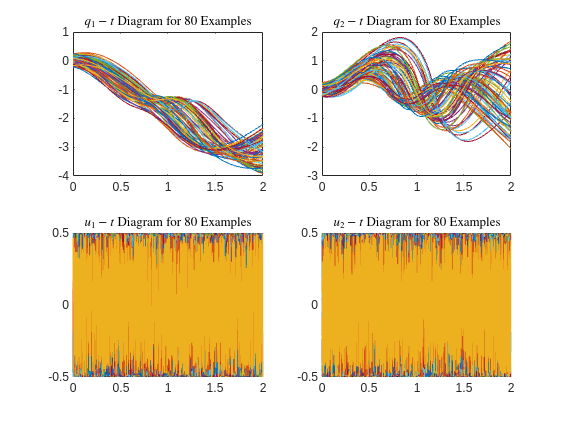

for sample=1:num_examples
    t=Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1),1);
    q1=Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1),2);
    q2=Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1),3);
    u1=Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1),6);
    u2=Data((sample-1)*(time_steps+1)+1:sample*(time_steps+1),7);
    subplot(2,2,1);
    plot(t,q1);
    hold on
    subplot(2,2,2);
    plot(t,q2);
    hold on
    subplot(2,2,3);
    plot(t,u1);
    hold on
    subplot(2,2,4);
    plot(t,u2);
    hold on
end

subplot(2,2,1);
hold off
% legend
title("$q_1 - t$ Diagram for "+num2str(num_examples)+" Examples","Interpreter","latex");
subplot(2,2,2);
hold off
% legend
title("$q_2 - t$ Diagram for "+num2str(num_examples)+" Examples","Interpreter","latex");
subplot(2,2,3);
hold off
% legend
title("$u_1 - t$ Diagram for "+num2str(num_examples)+" Examples","Interpreter","latex");
subplot(2,2,4);
hold off
% legend
title("$u_2 - t$ Diagram for "+num2str(num_examples)+" Examples","Interpreter","latex");

## 4. Save Data

save("Data/DoublePendulum.mat","Data")

## Utilities

$M$ Matrix


$$M=\left[
\begin{array}{cc}
 m_1 l_{\text{c1}}^2+2 m_2 l_1 l_{\text{c2}} \cos \left(q_2\right)+m_2
   \left(l_{\text{c2}}^2+l_1^2\right)+J_1+J_2 & m_2 l_1 l_{\text{c2}} \cos
   \left(q_2\right)+m_2 l_{\text{c2}}^2+J_2 \\
 m_2 l_1 l_{\text{c2}} \cos \left(q_2\right)+m_2 l_{\text{c2}}^2+J_2 & m_2
   l_{\text{c2}}^2+J_2 \\
\end{array}
\right]$$


function M=M_Matrix(t,State)
    global m1 m2 l1 lc1 lc2 J1 J2
    q2=State(2);
    M11=J1+J2+m1*lc1^2+m2*(l1^2+lc2^2)+2*m2*l1*lc2*cos(q2);
    M12=J2+m2*lc2^2+m2*l1*lc2*cos(q2);
    M22=J2+m2*lc2^2;
    M=[M11,M12;M12,M22];
end

$C$ Vector


$$C=\left(
\begin{array}{c}
- m_2 l_1 l_{\text{c2}} v_2 \sin
   \left(q_2\right) \left(2 v_1+v_2\right) \\
 m_2 l_1 l_{\text{c2}} \sin \left(q_2\right) v_1^2 \\
\end{array}
\right)$$


function C=C_Vector(t,State)
    global m2 l1 lc2
    q2=State(2);
    v1=State(3);
    v2=State(4);
    C1=-m2*l1*lc2*sin(q2)*v2*(2*v1+v2);
    C2=m2*l1*lc2*sin(q2)*v1^2;
    C=[C1;C2];
end

$G$ Vector


$$G=\left(
\begin{array}{c}
 g \left(\left(m_1 l_{\text{c1}}+ m_2 l_1\right) \cos \left(q_1\right) +m_2
   l_{\text{c2}} \cos \left(q_1+q_2\right)\right) \\
 g m_2 l_{\text{c2}} \cos \left(q_1+q_2\right) \\
\end{array}
\right)$$


function G=G_Vector(t,State)
    global m1 m2 l1 lc1 lc2 g
    q1=State(1);
    q2=State(2);
    G1=g*((m1*lc1+m2*l1)*cos(q1)+m2*lc2*cos(q1+q2));
    G2=g*m2*lc2*cos(q1+q2);
    G=[G1;G2];
end

State Space ODE

function dxdt=SS_ODE(t,x,u)
    dxdt=[x(3);x(4);M_Matrix(t,x)\(u-G_Vector(t,x)-C_Vector(t,x))];
end